% desinged by chen zhili
% 2023-10-21

实验报告3

01 系统y(n)-0.9y(n-8)=x(n)-x(n-8)的特性

b1 = [1 0 0 0 0 0 0 0 -1];
a1 = [1 0 0 0 0 0 0 0 -0.9];
figure(1)
sys_ana(b1,a1);

02-1 所设计滤波器h(n)=[1,-sqrt(2),1]

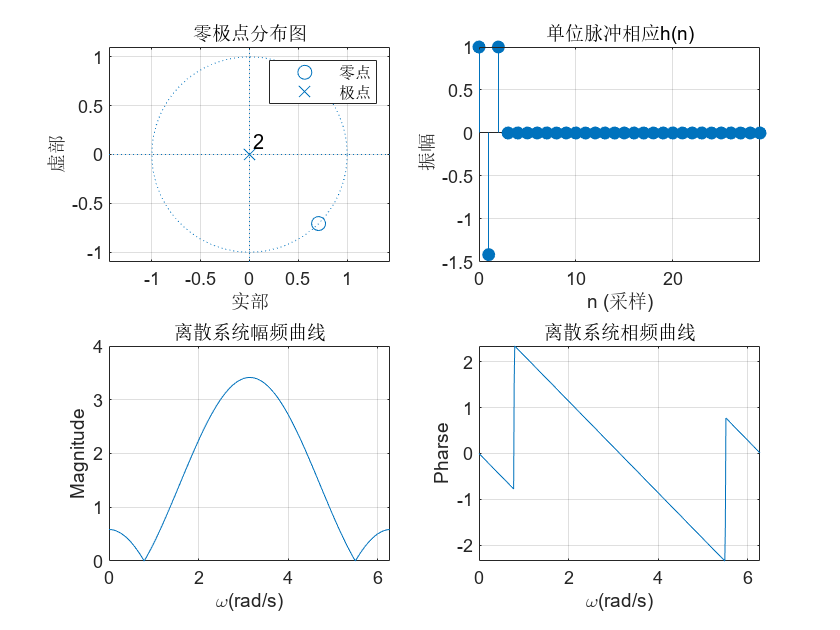

b2 = [1 -sqrt(2) 1];
a2 = [1 0 0];
figure(2)
sys_ana(b2, a2);

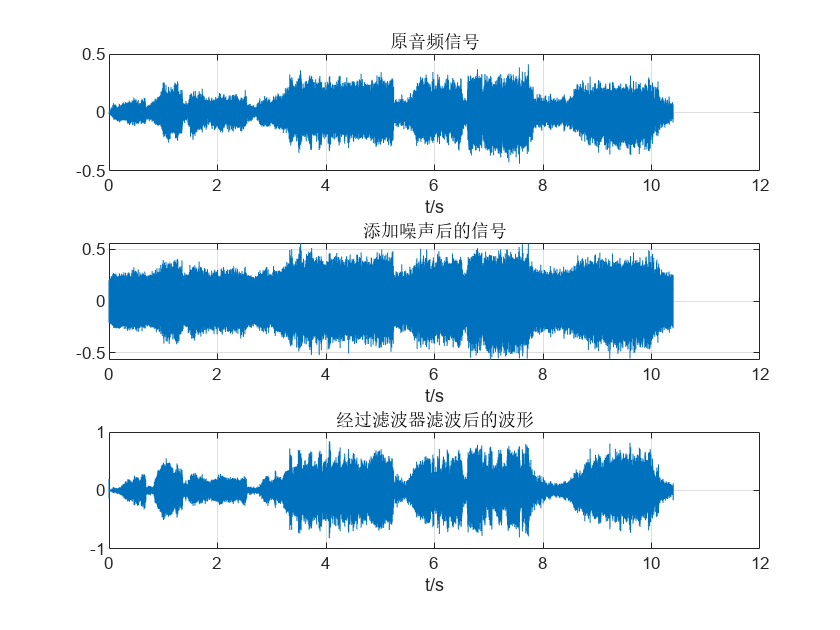

% 滤波前后的时域波形图
[xn, fs] = audioread('motherland.wav'); %读取音频信号
t=0:1/fs:(length(xn)-1)/fs;
%采样频率为fs，每个点之间的距离为1/fs秒，总共时间为(length(xn)-1)/fs
figure(3)
subplot(3,1,1);plot(t,xn); grid on; xlabel('t/s');
title('原音频信号');
xn_noise = xn.' + 0.2*cos(2000*pi*t); %给原信号每个点上添加相应的噪声值
subplot(3,1,2);plot(t,xn_noise);grid on;xlabel('t/s');
title('添加噪声后的信号');
hn = [1 -sqrt(2) 1];
y = conv(hn, xn_noise);  %经过卷积后，序列长度发生变化
t1 = 0:1/fs:(length(y)-1)/fs;
subplot(3,1,3);plot(t1,y);grid on;xlabel('t/s');
title('经过滤波器滤波后的波形');

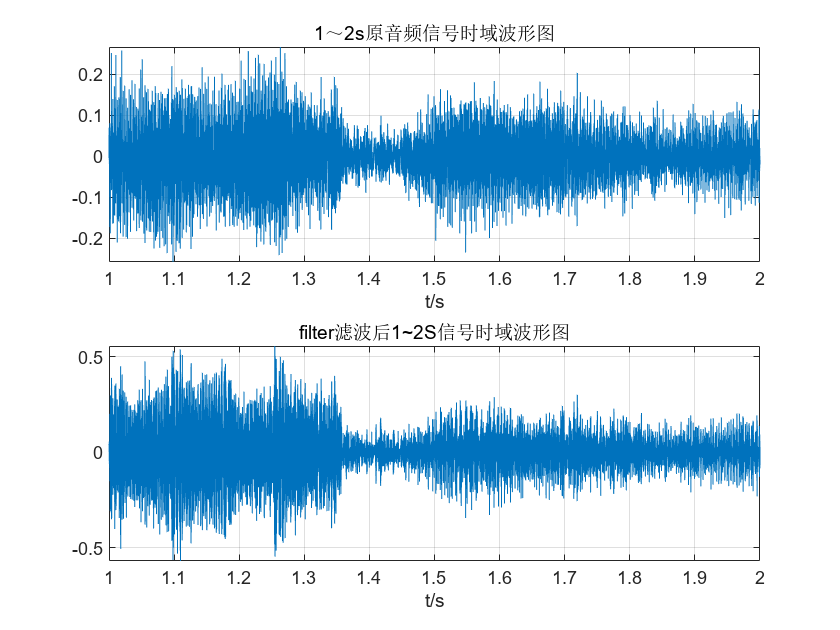

% 系统H1(z)、H2(Z)、H3(z)对'motherland.wav'滤波
% H1(z)对'motherland.wav'滤波
figure(4);
b1 = [1 0];
a1 = [1 0.8];
filters(b1,a1); 

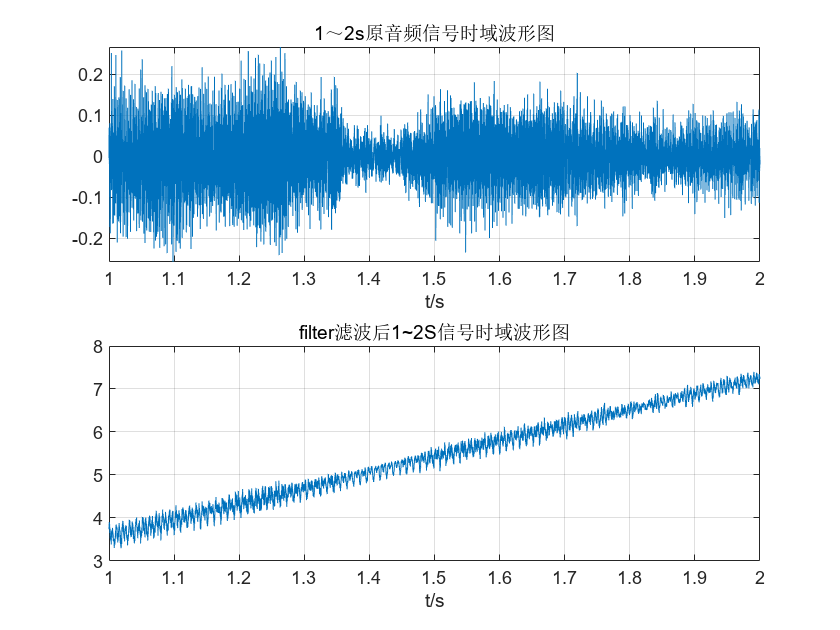

% H2(z)对'motherland.wav'滤波
figure(5);
b2 = [1 0];
a2 = [1 -1];
filters(b2,a2); 

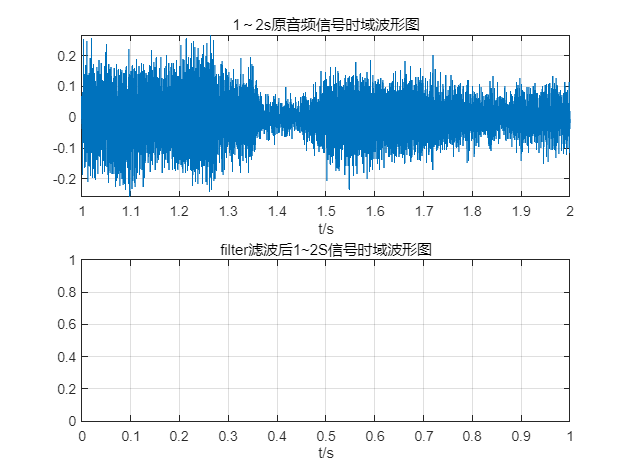

% H3(z)对'motherland.wav'滤波
figure(6);
b3 = [1 0];
a3 = [1 1.2];
filters(b3,a3); 

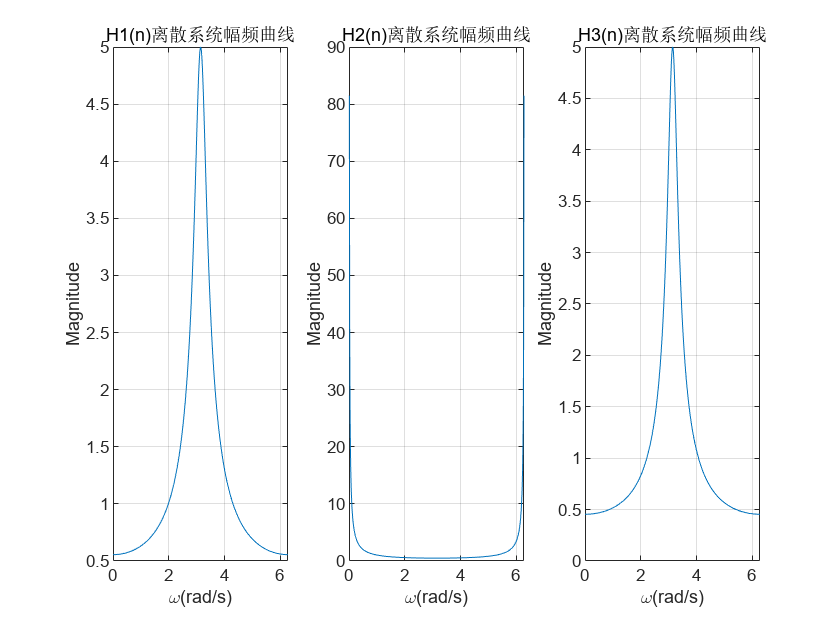

% 三个系统的幅频特性
[H1,w1]=freqz(b1,a1,'whole');
Hm1 = abs(H1);
Hp1 = angle(H1);
subplot(131)
plot(w1,Hm1);grid on
xlabel('\omega(rad/s)'),ylabel('Magnitude'),title('H1(n)离散系统幅频曲线')

[H2,w2]=freqz(b2,a2,'whole');
Hm2 = abs(H2);
Hp2 = angle(H2);
subplot(132)
plot(w2,Hm2);grid on
xlabel('\omega(rad/s)'),ylabel('Magnitude'),title('H2(n)离散系统幅频曲线')

[H3,w3]=freqz(b3,a3,'whole');
Hm3 = abs(H3);
Hp3 = angle(H3);
subplot(133)
plot(w3,Hm3);grid on
xlabel('\omega(rad/s)'),ylabel('Magnitude'),title('H3(n)离散系统幅频曲线')

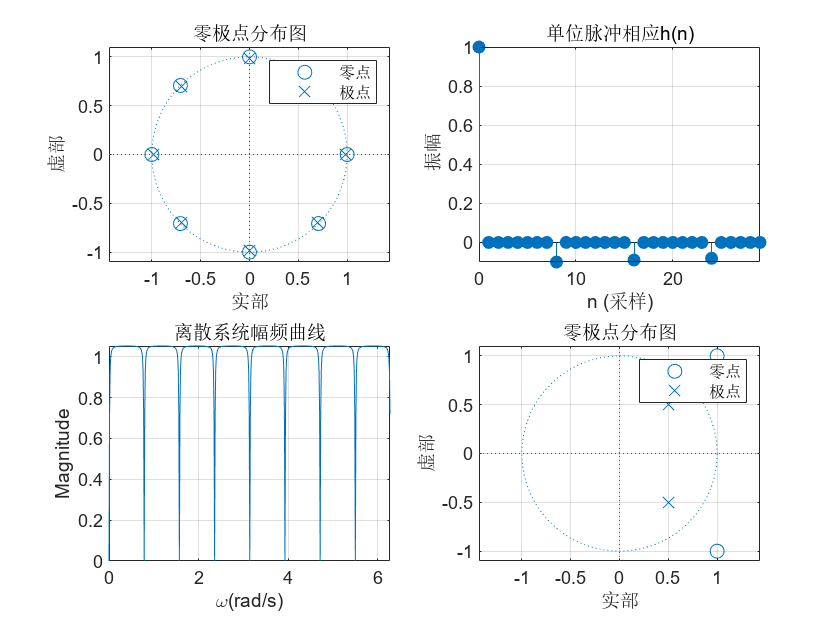

%  绘制出系统函数的零极点图
B = [1 -2 2];
A = [2 -2 1];
figure(1)
zplane(B,A);grid on
legend("零点",'极点');title('零极点分布图')

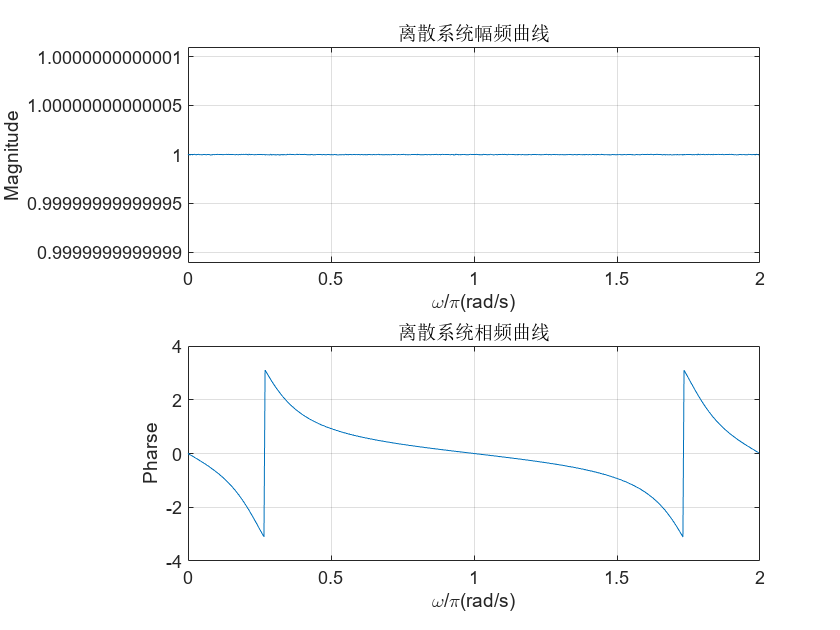

%  绘制出系统的幅频特性曲线
figure(7)
[H,w]=freqz(B,A,'whole');
Hm = abs(H);
Hp = angle(H);
subplot(211)
plot(w/pi,Hm);grid on
xlabel('\omega/\pi(rad/s)'),ylabel('Magnitude')
title('离散系统幅频曲线')
subplot(212)
plot(w/pi,Hp);grid on
xlabel('\omega/\pi(rad/s)'),ylabel('Pharse')
title('离散系统相频曲线')